% Util Functions
addpath(genpath('.\My5300Tools'));
addpath(genpath('.\Basic5300Tools'));
addpath(genpath(".\spotfi"));

% For each angle, the Tx device is placed at 8/9 locations with different distance.
% 30 packets are transmitted at each location.
% The collected CSI data of every angle is saved in one file.
% For example, the data collected at angle -10 is saved in file -10, which
% contains CSI data measured from 240 packets, i.e., 8 locations.

ang = -10;
file_path = ".\Data\AoAEstimation\still_test\"+ang;
N = GetNPackets(file_path);
disp(['angle', ' N_packet', ' N_location']);

angle N_packet N_location


disp([ang, N, N/30]);

   -10   240     8




disp("Timestamps for 240 Packtes"); % Correspond to 8 loactions

Timestamps for 240 Packtes


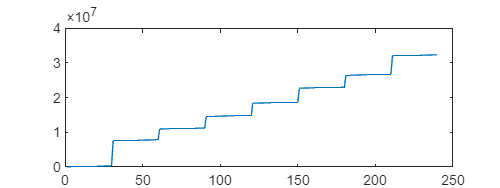

figure('Renderer', 'painters', 'Position', [10 10 400 150]);
plot(GetTimestamps(file_path));

% SpotFi: AoA Estimation
test_angles = -50:10:50;
oxs = ["", "_ox"];

% Calculate Phase Offset for Calibration
file_pre = ".\Data\AoAEstimation\calibration\data1_"

file_pre = ".\Data\AoAEstimation\calibration\0711_"

filePath = file_pre+"12";
P1 = GetPhaseDifByAntennaSeq(filePath, [1,2]);
filePath = file_pre+"21";
P2 = GetPhaseDifByAntennaSeq(filePath, [1,2]);
c21 = (P2 + P1)/2;
d21 = c21(:,1);
d21 = d21';

for data_index = 1:1:length(test_angles)
    for ox_i = 1:length(oxs)
        ang = test_angles(data_index);
        ox = oxs(ox_i);
        file_path = ".\Data\AoAEstimation\still_test\"+ang+ox
        csi_trace = readfile(file_path);

        Ntx = csi_trace{1}.Ntx; % Number of tx antennas
        Nrx = csi_trace{1}.Nrx; % Number of rx antennas
        Npacket = length(csi_trace);
        Nresults = 3; % Top n SpotFi results
        distance = 3; % cm Actual antenna distance
        theta = zeros(Ntx, Npacket, Nresults);

        % % 5G
        fc = 5.320e9; % center frequency
        M = 2;%Nrx;    % number of rx antennas
        fs = 40e6; % channel bandwidth
        c = 3e8;  % speed of light
        d = distance*0.01; % m  % distance between adjacent antennas in the linear antenna array
        SubCarrInd = [-58,-54,-50,-46,-42,-38,-34,-30,-26,-22,-18,-14,-10,-6,-2,2,6,10,14,18,22,26,30,34,38,42,46,50,54,58]; % WiFi subcarrier indices at which CSI is available
        N = length(SubCarrInd); % number of subcarriers
        fgap = fs/128;
        lambda = c/fc;  % wavelength
        T = 1; % number of transmitter antennas

        % MUSIC algorithm requires estimating MUSIC spectrum in a grid. paramRange captures parameters for this grid
        % For the following example, MUSIC spectrum is caluclated for 101 ToF (Time of flight) values spaced equally between -25 ns and 25 ns. MUSIC spectrum is calculated for for 101 AoA (Angle of Arrival) values between -90 and 90 degrees.
        paramRange = struct;
        paramRange.GridPts = [101 101 1]; % number of grid points in the format [number of grid points for ToF (Time of flight), number of grid points for angle of arrival (AoA), 1]
        paramRange.delayRange = [-100 100]*1e-9; % lowest and highest values to consider for ToF grid. 1~0.3m
        paramRange.angleRange = 90*[-1 1]; % lowest and values to consider for AoA grid.
        do_second_iter = 0;
        % paramRange.seconditerGridPts = [1 51 21 21];
        paramRange.K = floor(M/2)+1; % parameter related to smoothing.  
        paramRange.L = floor(N/2); % parameter related to smoothing.  
        paramRange.T = 1;
        paramRange.deltaRange = [0 0]; 

        maxRapIters = Inf;
        useNoise = 0;
        paramRange.generateAtot = 2;

        delayRange = paramRange.delayRange;
        deltaRange = paramRange.deltaRange;
        angleRange = paramRange.angleRange;
        GridPts = paramRange.GridPts;
        MaxAngle = angleRange(2);
        MinAngle = angleRange(1);
        [aTot,GridStart,GridSpacing, delayGridValue, u_sGridValue, deltaGridValue] = gridVecBackscatter(deltaRange, M, T, d, fc, c, do_second_iter, delayRange, SubCarrInd, N, fgap, GridPts, MaxAngle, MinAngle, paramRange.generateAtot);

        parfor index=1:Npacket
            csi_entry = csi_trace{index};
            csi_tmp = get_scaled_csi(csi_entry);

            tmp_theta = zeros(Ntx, Nresults);
            tmp_dis = zeros(Ntx, Nresults);
            for tx_index = 1:1:Ntx
                % Only consider measurements for transmitting on one antenna
                csi = csi_tmp(tx_index, :, :);
                % Remove the single element dimension
                csi = squeeze(csi);
                csi = csi(1:M,:);

                % Calibration
                csi(2,:) = abs(csi(2,:)).*cos(angle(csi(2,:))+d21)+1i*abs(csi(2,:)).*sin(angle(csi(2,:))+d21);

                csi = csi';
                sample_csi_trace = csi(:);
                % sample CSI trace is a 90x1 vector where first 30 elements correspond to subcarriers for first rx antenna, second 30 correspond to CSI from next 30 subcarriers and so on.
                % replace sample_csi_trace with CSI from Intel 5300 converted to 90x1 vector

                % ToF sanitization code (Algorithm 1 in SpotFi paper)
                csi_plot = reshape(sample_csi_trace, N, M);
                [PhsSlope, PhsCons] = removePhsSlope(csi_plot,M,SubCarrInd,N);
                ToMult = exp(1i* (-PhsSlope*repmat(SubCarrInd(:),1,M) - PhsCons*ones(N,M) ));
                csi_plot = csi_plot.*ToMult;
                relChannel_noSlope = reshape(csi_plot, N, M, T);
                sample_csi_trace_sanitized = relChannel_noSlope(:);

                % MUSIC algorithm for estimating angle of arrival
                % aoaEstimateMatrix is (nComps x 5) matrix where nComps is the number of paths in the environment. First column is ToF in ns and second column is AoA in degrees as defined in SpotFi paper
                aoaEstimateMatrix = backscatterEstimationMusicFast(aTot,GridStart,GridSpacing, delayGridValue, u_sGridValue, deltaGridValue,sample_csi_trace_sanitized, M, N, c, fc,...
                                    T, fgap, SubCarrInd, d, paramRange, maxRapIters, useNoise, do_second_iter, ones(Nresults))
                tofEstimate = aoaEstimateMatrix(:,1); % ToF in nanoseconds
                aoaEstomate = aoaEstimateMatrix(:,2); % AoA in degrees
                
                % Record AoA results
                tmp = zeros(Nresults-length(aoaEstomate), 1);
                aoaEstomate = [aoaEstomate; tmp];
                tmp_theta(tx_index, :) = aoaEstomate;

                theta(tx_index,index, :) = tmp_theta(tx_index, :);
            end
        end
        savePath = ['Data\AoAEstimation\still_test\Top', num2str(Nresults), '\', num2str(ang), num2str(ox), '.mat'];
        save( savePath, 'theta');
    end
end

file_path = ".\Data\AoAEstimation\still_test\-50"

file_path = ".\Data\AoAEstimation\still_test\-50_ox"

file_path = ".\Data\AoAEstimation\still_test\-40"

file_path = ".\Data\AoAEstimation\still_test\-40_ox"

file_path = ".\Data\AoAEstimation\still_test\-30"

file_path = ".\Data\AoAEstimation\still_test\-30_ox"

file_path = ".\Data\AoAEstimation\still_test\-20"

file_path = ".\Data\AoAEstimation\still_test\-20_ox"

file_path = ".\Data\AoAEstimation\still_test\-10"

file_path = ".\Data\AoAEstimation\still_test\-10_ox"

file_path = ".\Data\AoAEstimation\still_test\0"

file_path = ".\Data\AoAEstimation\still_test\0_ox"

file_path = ".\Data\AoAEstimation\still_test\10"

file_path = ".\Data\AoAEstimation\still_test\10_ox"

file_path = ".\Data\AoAEstimation\still_test\20"

file_path = ".\Data\AoAEstimation\still_test\20_ox"

file_path = ".\Data\AoAEstimation\still_test\30"

file_path = ".\Data\AoAEstimation\still_test\30_ox"

file_path = ".\Data\AoAEstimation\still_test\40"

file_path = ".\Data\AoAEstimation\still_test\40_ox"

file_path = ".\Data\AoAEstimation\still_test\50"

file_path = ".\Data\AoAEstimation\still_test\50_ox"

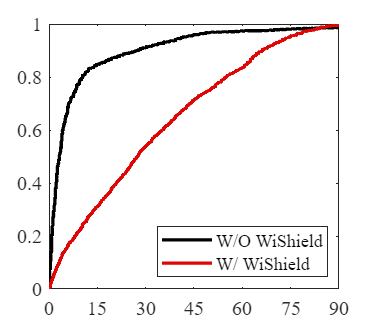

% Draw Still Test Error CDF
test_angles = -50:10:50;

% Without WiShield
err = [];
for data_index = 1:1:length(test_angles)
    ang = test_angles(data_index);
    file_path = ".\Data\AoAEstimation\still_test\Top3\"+ang+".mat";
    a = load(file_path);
    theta_noOx = a.theta;
    N = length(theta_noOx);
    err_tmp = zeros(1, N);
    for i = 1:N
        tmp = squeeze(abs(ang - theta_noOx(1, i, :)));
        err_tmp(i) = min(tmp);
    end
    err = [err, err_tmp];
    end
err_noOx = err;
[h, ] = cdfplot(err_noOx);
X_noOx = h.XData(2:end-1);
Y_noOx = h.YData(2:end-1);
close(gcf)

% With WiShield
err = [];
for data_index = 1:1:length(test_angles)
    ang = test_angles(data_index);
    file_path = ".\Data\AoAEstimation\still_test\Top3\"+ang+"_ox.mat";
    a = load(file_path);
    theta_Ox = a.theta;
    N = length(theta_Ox);
    err_tmp = zeros(1, N);
    for i = 1:N
        tmp = squeeze(abs(ang - theta_Ox(1, i, :)));
        err_tmp(i) = min(tmp);
    end
    err = [err, err_tmp];   
end
err_ox = err;
[h, ] = cdfplot(err_ox);
X_Ox = h.XData(2:end-1);
Y_Ox = h.YData(2:end-1);
close(gcf)

figure('Renderer', 'painters', 'Position', [10 10 300 260]);
plot(X_noOx, Y_noOx, "LineWidth", 2, "Color", 'black');
hold on;
plot(X_Ox, Y_Ox, "LineWidth", 2, "Color", [0.8745 0.0235 0.0235]);
hold off;
legend("W/O WiShield", "W/ WiShield", "Location","southeast");
set(gca,'FontName','Times New Roman','FontSize',12)
set(gca,'XTick',0:15:90);
axis([0 90 0 1])